% SHAPC-Mean and SHAPC-Var Comparison
alg = "RPSnet";
dataset = 'cifar10';
cls = 0;

if dataset == "cifar100"
    num_sessions = 10;
    cls_per_task = 10;
else
    num_sessions = 5;
    cls_per_task = 2;
end

algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", "der"];
if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end
num_algs = length(algs);

file_path = sprintf("%s_all_inclass_shapcs.mat", dataset);
if isfile(file_path)
    all_inclass_shapcs = load(file_path).all_inclass_shapcs;
else
    all_inclass_shapcs = zeros(((num_sessions-1)*cls_per_task), num_algs+1);
end

% Load SHAPC values (First and Last 1000)
save_path = sprintf("%s/%s/shapc_vals_inclass.mat", alg, dataset);
if isfile(save_path)
    inclass_struct = load(save_path);

    for i=1:((num_sessions-1)*cls_per_task)
        cls = i - 1;

        cls_str = sprintf("cls%d", cls);
        shapc_struct = inclass_struct.(cls_str);
       
        % Load SHAPC values all
        shapc_avgs = [];
        pair_str = 'sc' + string(floor(cls/2)) + string(num_sessions-1);
        shapcs = [];
        sample_list = string(fieldnames(shapc_struct.(pair_str)));
        for k=1:length(fieldnames(shapc_struct.(pair_str)))
            sample_str = sample_list(k);%'sample' + string(k-1);
            shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
        end
        shapc_avgs = [shapc_avgs; mean(shapcs)];
        
        % Note the shapc is represented as percentage
        %disp("From averaging all tasks together:")
        shapc_mean_perc = mean(shapc_avgs);
        shapc_mean = mean(shapc_avgs) / 100;
        
        
        % Display Results
        fprintf('SHAPC Mean Percentage: %.2f%%\n', shapc_mean_perc);
        fprintf('SHAPC Mean: %.4f\n', shapc_mean);
        
        if ~exist('inclass_shapcs','var')
            inclass_shapcs = zeros(((num_sessions-1)*cls_per_task),2);
        end
        
        inclass_shapcs(cls+1,1) = cls;
        inclass_shapcs(cls+1,2) = shapc_mean_perc;
    end
    all_inclass_shapcs(:, find(algs==alg)+1) = inclass_shapcs(:,2);
end

SHAPC Mean Percentage: 22.15%


SHAPC Mean: 0.2215


SHAPC Mean Percentage: 22.23%


SHAPC Mean: 0.2223


SHAPC Mean Percentage: 22.25%


SHAPC Mean: 0.2225


SHAPC Mean Percentage: 21.73%


SHAPC Mean: 0.2173


SHAPC Mean Percentage: 23.53%


SHAPC Mean: 0.2353


SHAPC Mean Percentage: 22.87%


SHAPC Mean: 0.2287


SHAPC Mean Percentage: 25.59%


SHAPC Mean: 0.2559


SHAPC Mean Percentage: 25.39%


SHAPC Mean: 0.2539


save(file_path, "all_inclass_shapcs")

% Display All Results
fprintf('Inclass SHAPC-Mean Percentages:\n');

Inclass SHAPC-Mean Percentages:


disp(inclass_shapcs);

         0   22.1465
    1.0000   22.2274
    2.0000   22.2540
    3.0000   21.7252
    4.0000   23.5257
    5.0000   22.8738
    6.0000   25.5946
    7.0000   25.3918




fprintf('Std Dev:\n');

Std Dev:


disp(std(inclass_shapcs(:,2)))

    1.5059




fprintf('Avg:\n');

Avg:


disp(mean(inclass_shapcs(:,2)))

   23.2174



create_table = true;
if create_table
    if ~exist('inclass_shapcs','var')
        all_inclass_shapcs = load(file_path);
    end

    % Create a table for better visualization of results
    all_inclass_shapcs(:, 1) = (1:(num_sessions-1)*cls_per_task)-1;
    resultsTable = array2table(all_inclass_shapcs, 'VariableNames', ['Class' algs]);
    disp(resultsTable);

    all_std_devs = [NaN std(all_inclass_shapcs(:, 2:end))];
    fprintf('Std Devs:\n');
    disp(all_std_devs);

    all_avgs = [NaN mean(all_inclass_shapcs(:, 2:end))];
    fprintf('Averages:\n');
    disp(all_avgs);
end

    Class    iTAML     RPSnet    foster     memo      der  
    _____    ______    ______    ______    ______    ______

      0      23.453    22.146    21.326    21.947    23.564
      1      29.437    22.227     23.58    26.948    30.769
      2      26.526    22.254    25.543    27.079    35.919
      3       26.74    21.725    25.018    26.622    31.394
      4      29.908    23.526    29.863    30.653    46.811
      5      32.587    22.874    32.244    31.503    49.086
      6      40.018    25.595    35.224    36.406    60.525
      7      39.916    25.392    36.908    35.504    57.204



Std Devs:


       NaN    6.1185    1.5059    5.7066    4.8804   13.4331



Averages:


       NaN   31.0731   23.2174   28.7132   29.5829   41.9089




% Cls 7 has the highest SHAPCs for all algs
% Except for foster -> Cls 8

% Cls 1 has the lowest SHAPCs for all algs
% Except for RPSnet -> Cls 4

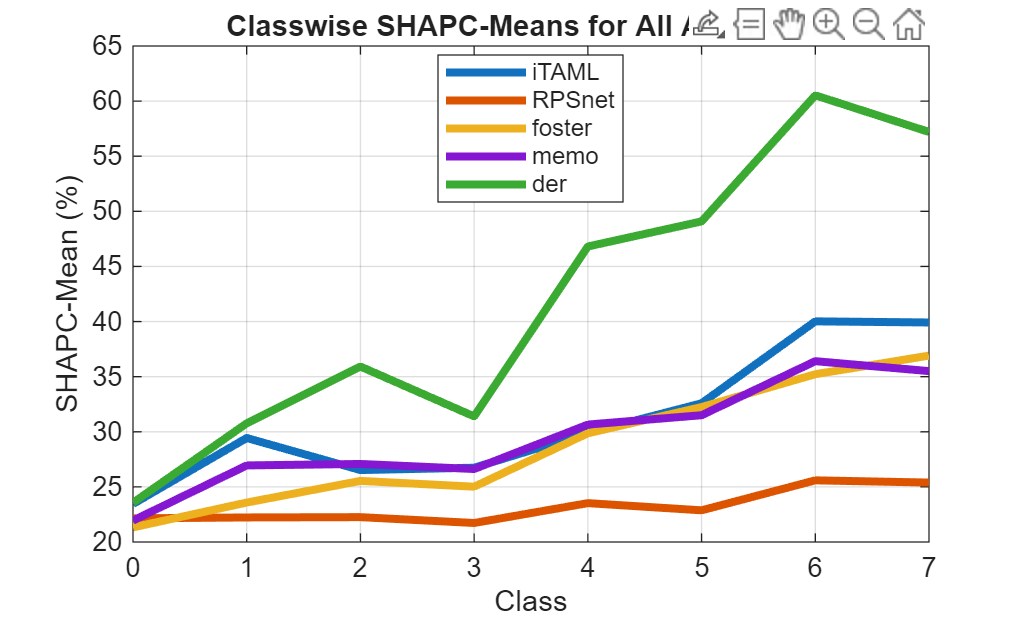

% Plot inclass shapcs

plot((all_inclass_shapcs(:, 1)), ...
    (all_inclass_shapcs(:, 2:end)), ...
    'LineWidth', 3)
title('Classwise SHAPC-Means for All Algorithms');
xlabel('Class');
ylabel('SHAPC-Mean (%)');
legend(algs,"Location", "best")
grid on;